%creating the histogram
c21 = c21(:);
clf;
hold on;
LegHandles = []; LegText = {};
[CdfF,CdfX] = ecdf(c21,'Function','cdf');  % compute empirical cdf
BinInfo.rule = 1;
[~,BinEdge] = internal.stats.histbins(c21,[],[],BinInfo,CdfF,CdfX);
[BinHeight,BinCenter] = ecdfhist(CdfF,CdfX,'edges',BinEdge);
hLine = bar(BinCenter,BinHeight,'hist');
set(hLine,'FaceColor','none','EdgeColor',[0 0 1],...
    'LineStyle','-', 'LineWidth',1);
xlabel('Counts per Interval');
ylabel('Normalized Distribution of Counts')
LegHandles(end+1) = hLine;
LegText{end+1} = 'c21 data';
XLim = get(gca,'XLim');
XLim = XLim + [-1 1] * 0.01 * diff(XLim);
XContinuous = linspace(XLim(1),XLim(2),100);
XIncr = max(1,floor((XLim(2)-XLim(1))/100));
XDiscrete = floor(XLim(1)):XIncr:ceil(XLim(2));
%creating the error bars
elements=[3 18 26 18 18 8 6 2 0 0 1];
normalizedelements=[0.03 0.18 0.26 0.18 0.18 0.08 0.06 0.02 0 0 0.01];
bincenters= 0.5:1:10.5;
err=sqrt(elements)/100;
bar(bincenters, normalizedelements);

errorbar(bincenters,normalizedelements, err,'o');
%creating the gaussian fit
pd1 = fitdist(c21, 'normal')

pd1 =   NormalDistribution

  Normal distribution
       mu =    2.97   [2.61054, 3.32946]
    sigma = 1.81161   [1.5906, 2.1045]


XGrid = XContinuous;
YPlot = pdf(pd1,XGrid);
hLine = plot(XGrid,YPlot,'Color',[1 0 0],...
    'LineStyle','-', 'LineWidth',2,...
    'Marker','none', 'MarkerSize',6);
LegHandles(end+1) = hLine;
LegText{end+1} = 'fit 1';
%creating the poisson fit
pd2 = fitdist(c21, 'poisson')

pd2 =   PoissonDistribution

  Poisson distribution
    lambda = 2.97   [2.63223, 3.30777]


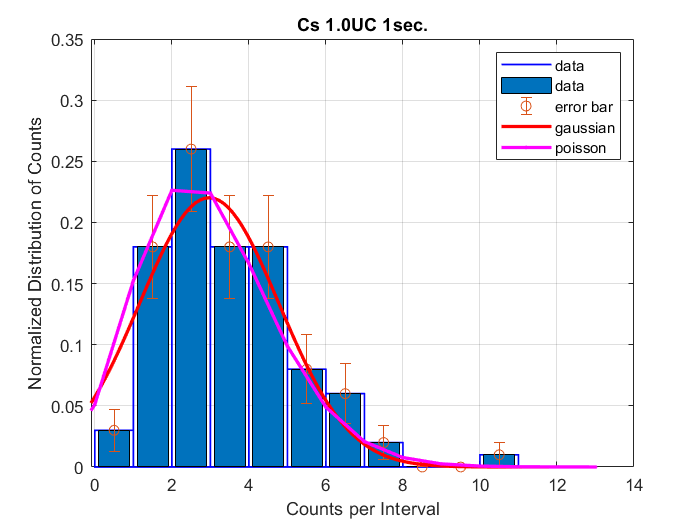

XGrid = XDiscrete;
YPlot = pdf(pd2,XGrid);
hLine = plot(XGrid,YPlot,'Color',[1 0 1],...
    'LineStyle','-', 'LineWidth',2,...
    'Marker','.', 'MarkerSize',6);
LegHandles(end+1) = hLine;
LegText{end+1} = 'fit 2';
legend({'data','data','error bar', 'gaussian','poisson'})


box on;
hold off;
grid on

xlim([-0.1 14.0])
ylim([0.000 0.350])
title('Cs 1.0UC 1sec.')